# Kaskadierung mit P und PID-Regler

Im unterlagertem Regelkreis wird die Manteltemperatur mit einem P-Regler geregelt. Der überlagerte Regelkreis und damit die Zellentemperatur werden durch einen PID-Regler geregelt.

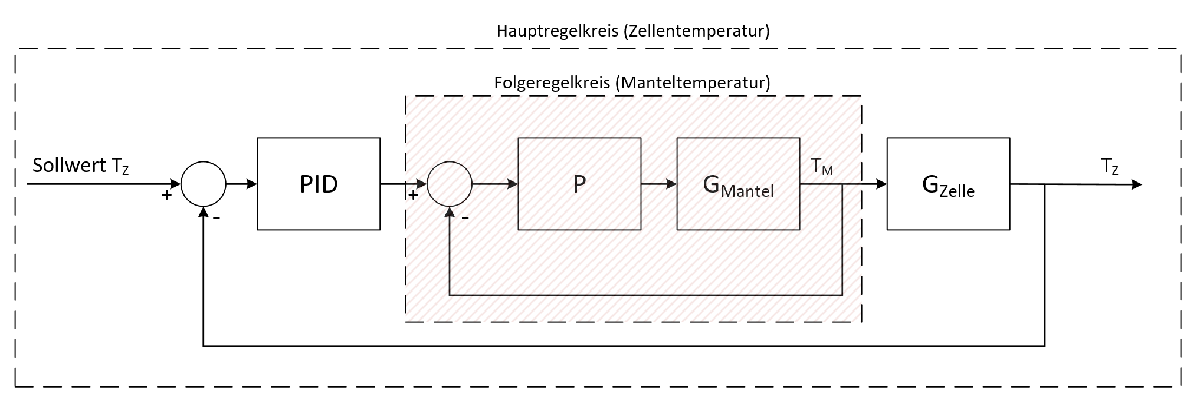

%---------------------------------------------------------
%Streckenparameter Mantel
K_M=2408;
T_M=12160;
G_Mantel=tf([K_M],[T_M 1])


G_Mantel =
 
     2408
  -----------
  12160 s + 1
 
Continuous-time transfer function.



%---------------------------------------------------------
%Strecke Zelle
K_Z =2321/K_M;
T1_Z=807;
T2_Z=5;
G_Zelle=tf([K_Z],[T2_Z*T1_Z T2_Z+T1_Z 1])


G_Zelle =
 
         0.9639
  --------------------
  4035 s^2 + 812 s + 1
 
Continuous-time transfer function.



%---------------------------------------------------------
%Regler Mantel
Kp_M=5;

# Unterlagerter Regelkreis

Übertragungsfunktion des unterlagertem Regelkreis:


$$G_{\mathrm{ges}\text{ }M\left(s\right)\text{ }} =\frac{G_O }{1+G_O }=\frac{\frac{K_{P_M} \cdot K_M }{\left.{\left(T\right.}_M \cdot s+1\right)}}{1+\frac{K_{P_M} \cdot K_M }{\left.{\left(T\right.}_M \cdot s+1\right)}}=\frac{K_{P_M} \cdot K_M }{T_M \cdot s+1+K_{P_M} \cdot K_M }=\frac{\frac{K_{P_M} \cdot K_M }{\left(K_{P_M} \cdot K_M +1\right)}}{\frac{T_M \cdot s}{\left(K_{P_M} \cdot K_M +1\right)}+1}\text{ }$$
 

Die Übertragungsfunktion der Zelle wird nun mit der Übertragungsfunktion des unterlagertem Regelkreises erweitert. 


$${G_{\mathrm{Srecke}} =\text{ }G}_{\mathrm{ges}\text{ }M\left(s\right)\text{ }} \cdot G_{\mathrm{Zelle}}$$


%---------------------------------------------------------
%Geschlossener Regelkreis von G_Mantel * G_Regler 
%Innere Kaskade
Gges_M=tf([(K_M*Kp_M)/(K_M*Kp_M+1)],[T_M/(K_M*Kp_M+1) 1])    


Gges_M =
 
    0.9999
  ----------
  1.01 s + 1
 
Continuous-time transfer function.



%Strecke Innere Kaskade + Zelle
G_Strecke=Gges_M*G_Zelle                                       


G_Strecke =
 
              0.9638
  -------------------------------
  4075 s^3 + 4855 s^2 + 813 s + 1
 
Continuous-time transfer function.



a=G_Strecke.Numerator{end};     %K der Strecke bestimmen
K_S=a(end);

Wendepunkt bestimmen um Tangente einzuzeichnen

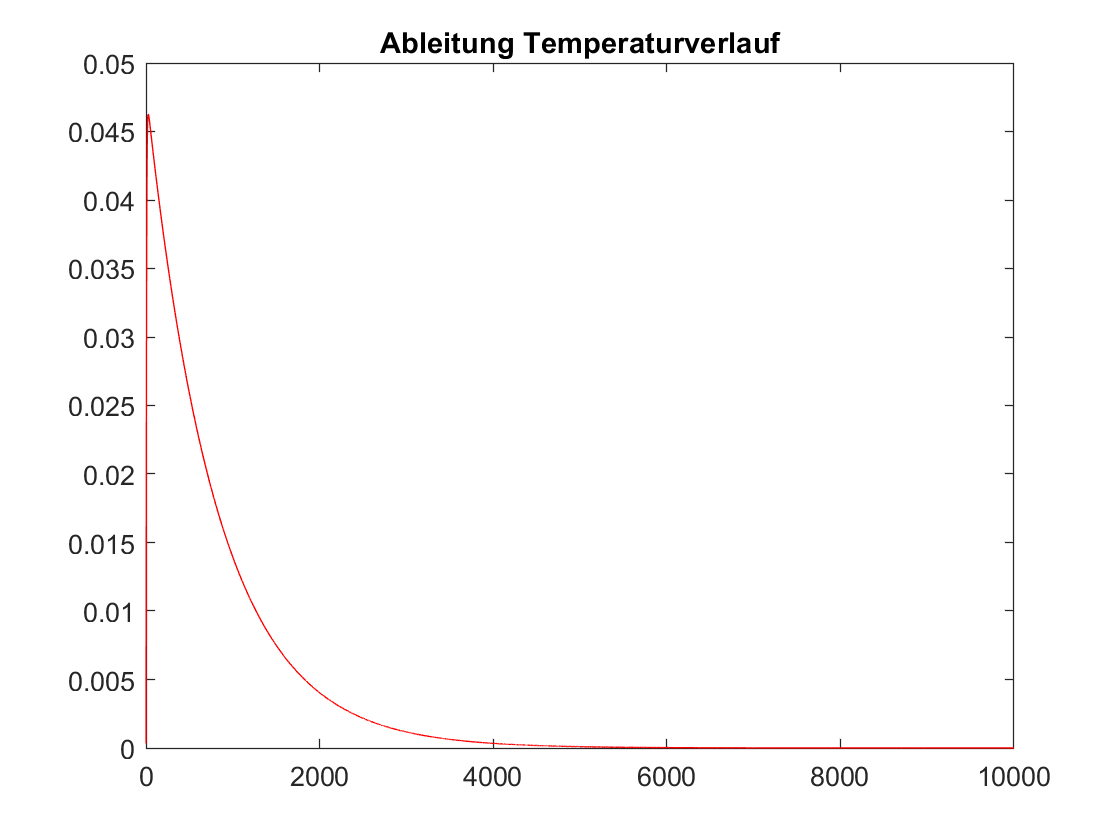

%---------------------------------------------------------
%Ableitung der Funktion durchführen um Wendepunkt zu bestimmen
G_Z_Strecke=c2d(G_Strecke,0.5);
sim('Sprung_Strecke');
figure('Name','Differential')
dT=diff(Sprung.signals.values);
t=Sprung.time;
dT(end+1:end+1) = 0; 
plot(Sprung.time, dT,'r')
title('Ableitung Temperaturverlauf')

[A,B]=max(dT);      %Max-Wert finden und zur welcher Zeit
k=B-1; % Wendepunkt
%---------------------------------------------------------

Wendetangente einzeichnen

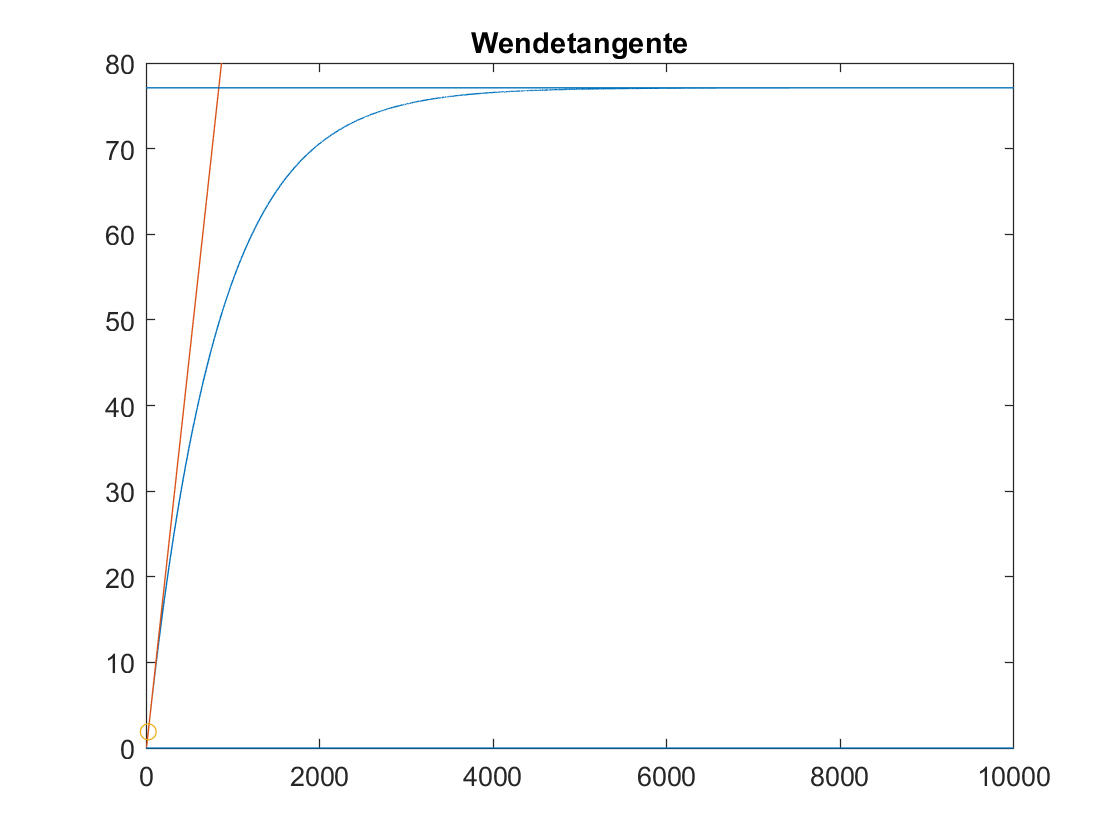

figure('Name','Wendetangente')
y=Sprung.signals.values;
t=Sprung.time;
plot(t,y)
axis([0 10000 0 80])
dy=diff(y)./diff(t);
tang=(t-t(k))*dy(k)+y(k);
hold on
plot(t,tang);
scatter(t(k),y(k));
ymax=y(end:end);
line([0 10000], [ymax ymax])
ymin=y(1:1);
line([0 10000], [ymin ymin])
hold off
title('Wendetangente')

Tu sowie Tg im Graph ermitteln um die Regelparameter des PID-Reglers zu bestimmen

%Tu vom Sprung herausfinden muss um 1 subtrahiert werden
[I Tu]=min(abs(tang(:,1)-0));       
%Tg vom Sprung herausfinden muss um 1 subtrahiert werden
[I Tg]=min(abs(tang(:,1)-max(y)));      

Tu_S=Tu/2-1              %Tu_S von der Strecke

Tu_S = 5

Tg_S=(Tg/2-1)-Tu_S      %Tg von der Strecke

Tg_S = 833

# PID-Regler

Reglerparameter des überlagertem Regelkreises bestimmen. In einem ersten Schritt durch Ziegler/Nichols und anschliessen durch Chien/Hrones und Reswick.

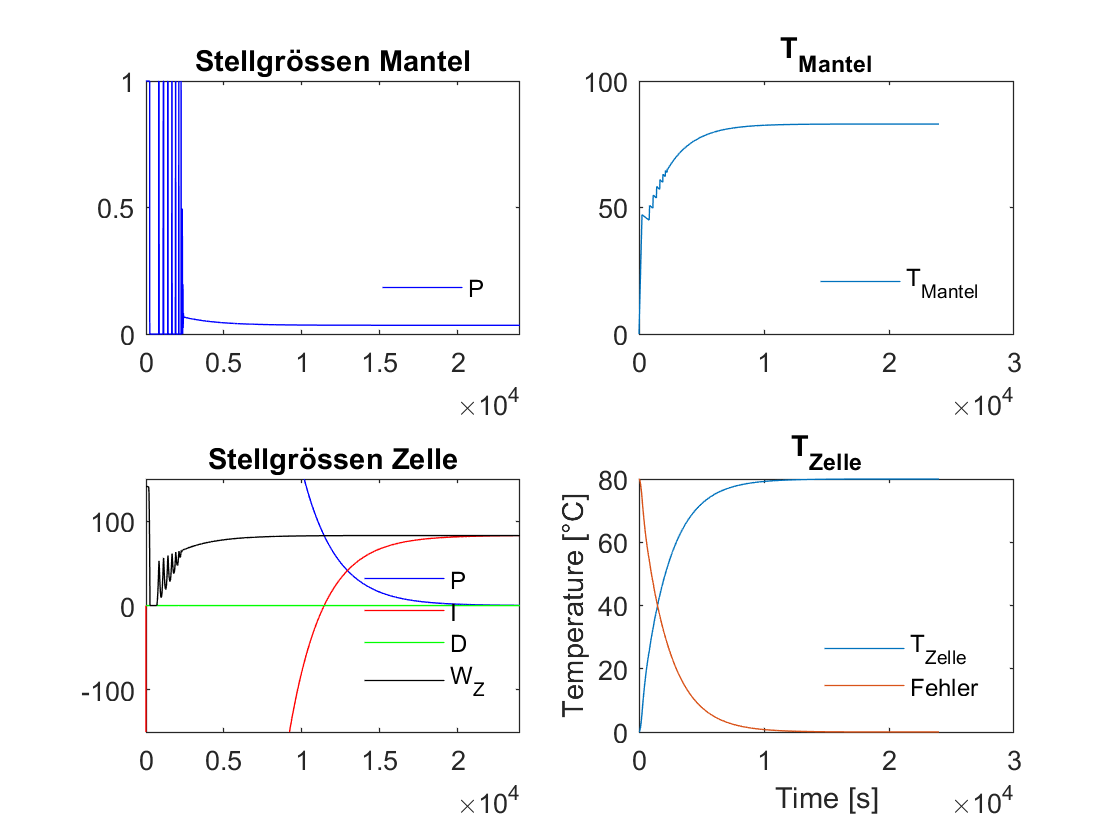

%Ziegler/Nichols
%PID Regler
Kp_S=(1.2*Tg_S)/(K_S*Tu_S);
Tn_S=2*Tu_S;
Ki_S=K_S/Tn_S;
Tv_S=0.5*Tu_S;
Kd_S=K_S*Tv_S;
Tt_S=sqrt(Tn_S*Tv_S);

% Simulation
sim('Regler_Kaskadierung_2');

figure('Name','Temperaturverlauf Mantel');
subplot(2,2,1);
plot(P_M.time, P_M.signals.values,'b')
title('Stellgrössen Mantel')
legend('P','Location','southeast') ;legend('boxoff')
axis([0 24000 0  1]) 
subplot(2,2,2);
plot(T_M.time,T_M.signals.values)
title('T_{Mantel}')
legend('T_{Mantel}','Location','southeast') ;legend('boxoff')
subplot(2,2,3);
plot(P_Z.time, P_Z.signals.values,'b', I_Z.time, I_Z.signals.values, 'r', ...
    D_Z.time, D_Z.signals.values,'g', W_Z.time, W_Z.signals.values ,'k')
title('Stellgrössen Zelle')
legend('P','I','D','W_Z','Location','southeast') ;legend('boxoff')
axis([0 24000 -150  150]) 
subplot(2,2,4);
plot(T_Z.time, T_Z.signals.values, E_Z.time, E_Z.signals.values)
title('T_{Zelle}')
ylabel('Temperature [°C]'); xlabel('Time [s]'); 
legend('T_{Zelle}','Fehler','Location','southeast') ;legend('boxoff')

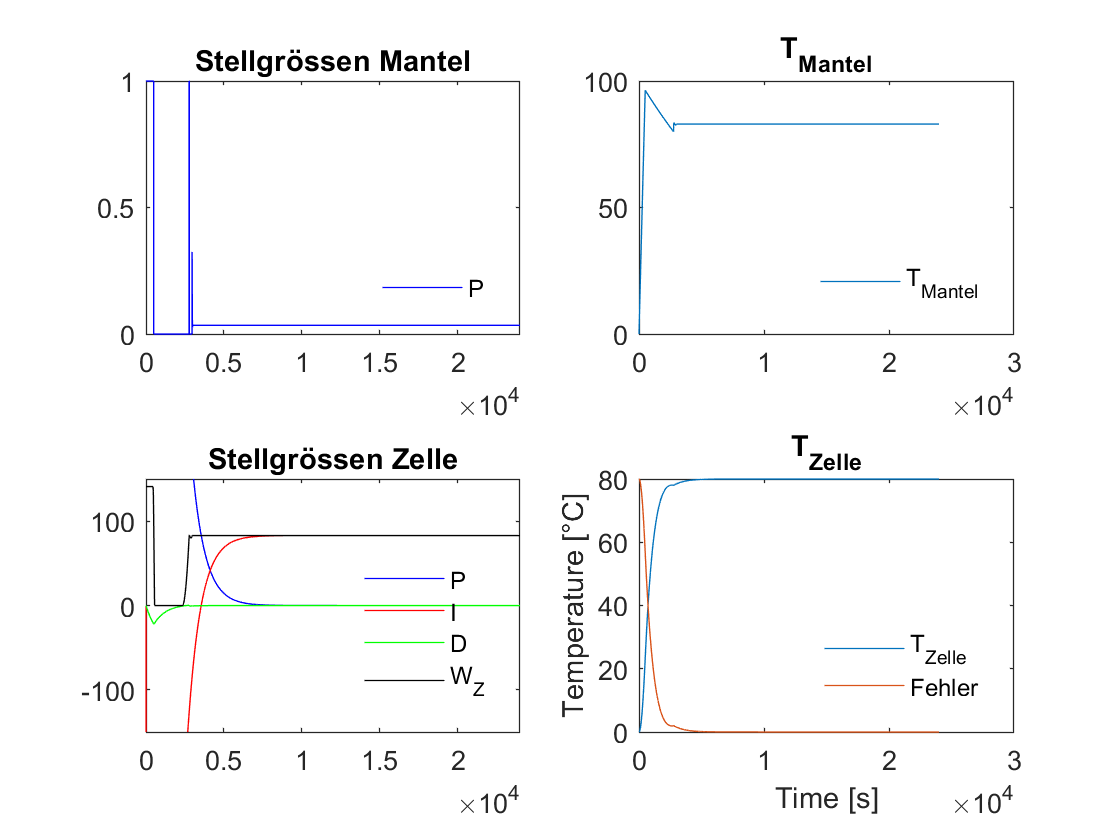

%Chien/Hrones und Reswick.
Kp_S=(0.6*Tg_S)/(K_S*Tu_S);
Tn_S=1*Tg_S;
Ki_S=Kp_S/Tn_S;
Tv_S=0.5*Tu_S;
Kd_S=Kp_S*Tv_S;
Tt_S=sqrt(Tn_S*Tv_S);       %Antiwindup

% Simulation
sim('Regler_Kaskadierung_2');

figure('Name','Temperaturverlauf Mantel');
subplot(2,2,1);
plot(P_M.time, P_M.signals.values,'b')
title('Stellgrössen Mantel')
legend('P','Location','southeast') ;legend('boxoff')
axis([0 24000 0  1]) 
subplot(2,2,2);
plot(T_M.time,T_M.signals.values)
title('T_{Mantel}')
legend('T_{Mantel}','Location','southeast') ;legend('boxoff')
subplot(2,2,3);
plot(P_Z.time, P_Z.signals.values,'b', I_Z.time, I_Z.signals.values, 'r', ...
    D_Z.time, D_Z.signals.values,'g', W_Z.time, W_Z.signals.values ,'k')
title('Stellgrössen Zelle')
legend('P','I','D','W_Z','Location','southeast') ;legend('boxoff')
axis([0 24000 -150  150]) 
subplot(2,2,4);
plot(T_Z.time, T_Z.signals.values, E_Z.time, E_Z.signals.values)
title('T_{Zelle}')
ylabel('Temperature [°C]'); xlabel('Time [s]'); 
legend('T_{Zelle}','Fehler','Location','southeast') ;legend('boxoff')